Matlab code for the Course: **Modelling and Simulation Mechatronics System (2020)**

by Enrico Bertolazzi

Dipartimento di Ingegneria Industriale

Universita` degli Studi di Trento

email: [enrico.bertolazzi@unitn.it](mailto:enrico.bertolazzi@unitn.it)

#### Add path for the library

addpath('../matlab');
addpath('../matlab/DAE');
addpath('../matlab/DAE_lib');

#### Initialize by cleaning memory and widows

close all;

#### Initialize parameters of the model and instantiate model class

mass    = 1;
gravity = 9.81;
ell     = 1;
DAE     = Pendulum3D_DAE( mass, gravity, ell );

#### Initialize the solver class

solver = DAE3TaylorSolver();
solver.setDAE( DAE );

#### Initialize the range where solution is computed and initial conditions

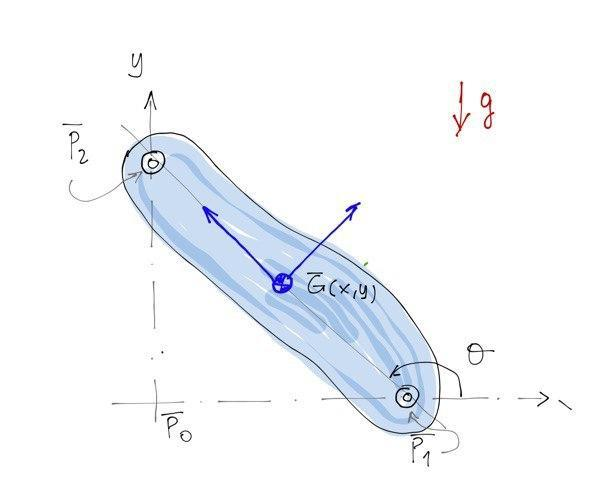

T     = 5;
DT    = 0.01;
theta = pi/2;
alpha = pi/2;

x     = ell*sin(theta)*cos(alpha);
y     = ell*sin(theta)*sin(alpha);
z     = ell*cos(theta);
vx    = 0;
vy    = 0;
vz    = 0;
p0    = [ x, y, z ];
v0    = [ vx, vy, vz ];

#### Advance the DAE (using not stabilized index-1 DAE)

tt  = 0:DT:T;
tt1 = 0:DT/2:T;
tt2 = 0:DT/10:T;
[p, v, lambda]  = solver.advance_simple( tt,  p0, v0 );
[p1,v1,lambda1] = solver.advance_simple( tt1, p0, v0 );
[p2,v2,lambda2] = solver.advance_simple( tt2, p0, v0 );

#### plot solution

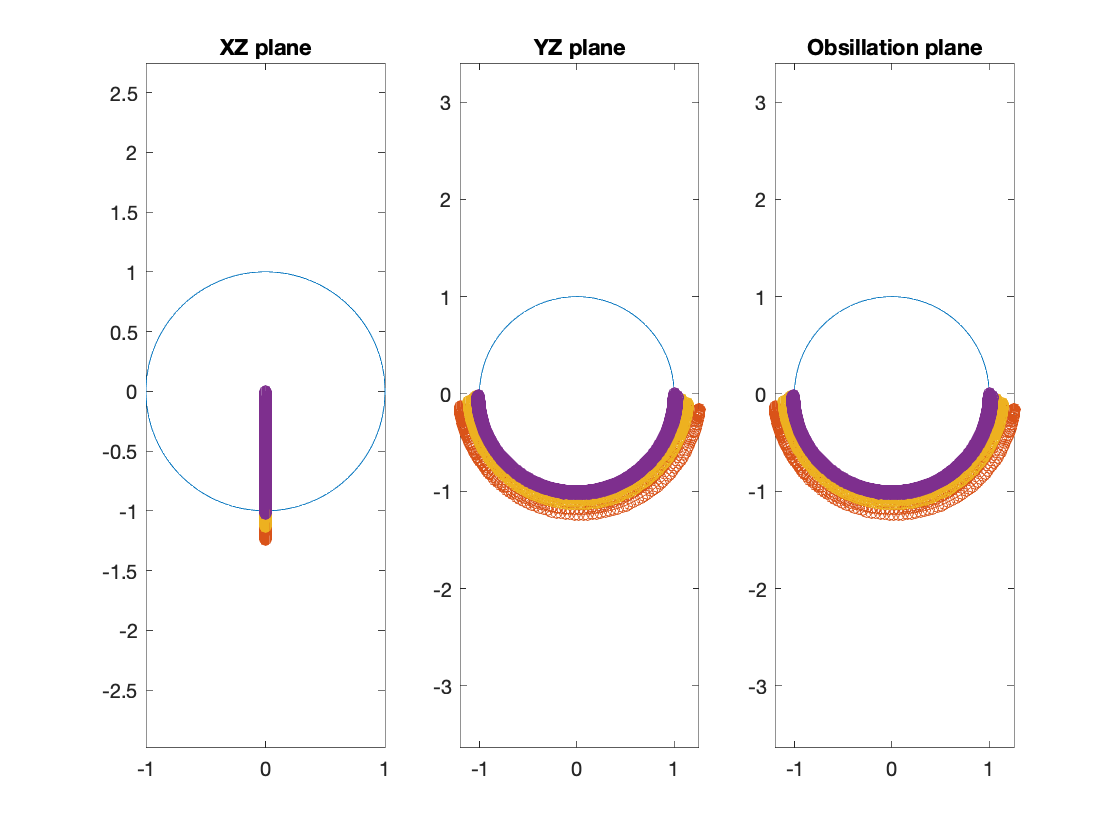

figure();
subplot(1,3,1);
plot( sin(0:pi/100:2*pi), cos(0:pi/100:2*pi), 'Linewidth', 0.2);
hold on;
plot( p(1,:),  p(3,:),  'o-', 'Linewidth', 0.2);
plot( p1(1,:), p1(3,:), 'o-', 'Linewidth', 0.2);
plot( p2(1,:), p2(3,:), 'o-', 'Linewidth', 0.2);
title('XZ plane');
axis equal;
hold off;

subplot(1,3,2);
plot( sin(0:pi/100:2*pi), cos(0:pi/100:2*pi), 'Linewidth', 0.2);
hold on;
plot( p(2,:),  p(3,:),  'o-', 'Linewidth', 0.2);
plot( p1(2,:), p1(3,:), 'o-', 'Linewidth', 0.2);
plot( p2(2,:), p2(3,:), 'o-', 'Linewidth', 0.2);
title('YZ plane');
axis equal;
hold off;  

subplot(1,3,3);
plot( sin(0:pi/100:2*pi), cos(0:pi/100:2*pi), 'Linewidth', 0.2);
hold on;
xy  = p(1,:)*cos(alpha)+p(2,:)*sin(alpha);
xy1 = p1(1,:)*cos(alpha)+p1(2,:)*sin(alpha);
xy2 = p2(1,:)*cos(alpha)+p2(2,:)*sin(alpha);
plot( xy,  p(3,:),  'o-', 'Linewidth', 0.2);
plot( xy1, p1(3,:), 'o-', 'Linewidth', 0.2);
plot( xy2, p2(3,:), 'o-', 'Linewidth', 0.2);
title('Obsillation plane');
axis equal;
hold off

#### Advance the DAE (using  stabilized index-1 DAE)

set parameter

eta   = 0.5;
omega = 4;

advance

tt  = 0:DT:T;
tt1 = 0:DT/2:T;
tt2 = 0:DT/10:T;
[p, v, lambda ] = solver.advance_Baumgarte( tt,  p0, v0, eta, omega );
[p1,v1,lambda1] = solver.advance_Baumgarte( tt1, p0, v0, eta, omega );
[p2,v2,lambda2] = solver.advance_Baumgarte( tt2, p0, v0, eta, omega );

#### plot solution

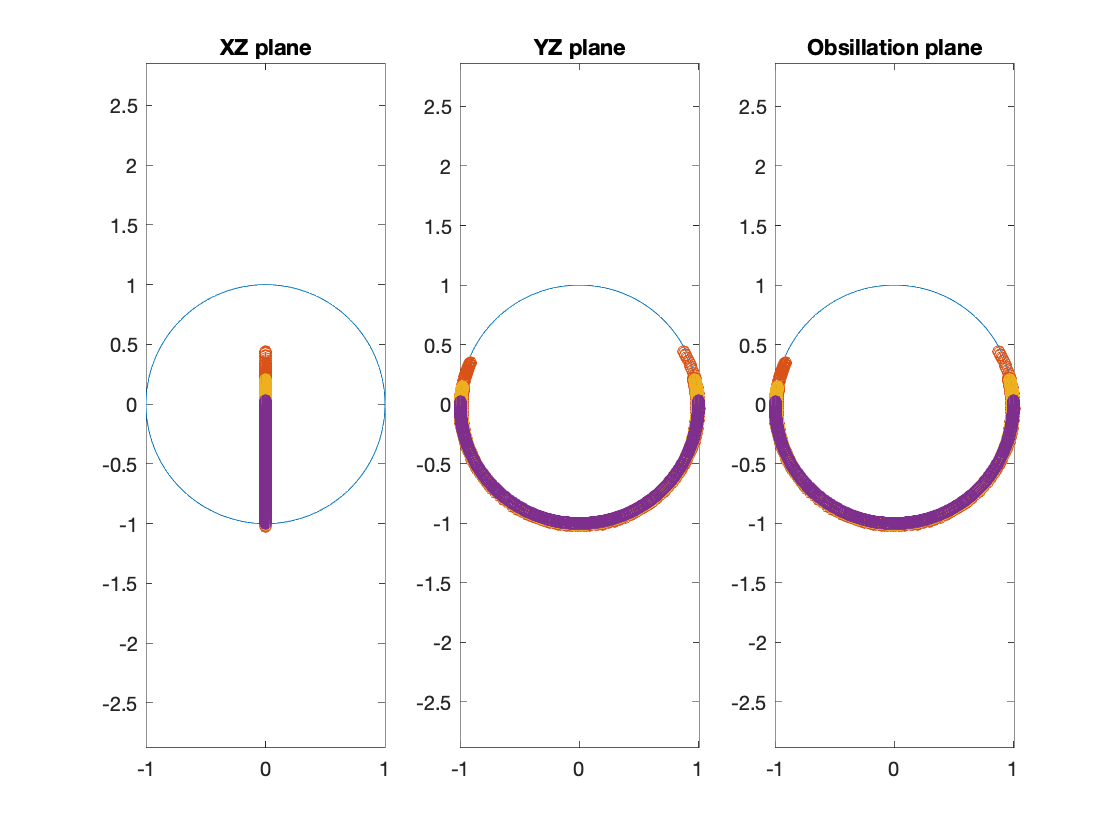

figure();
subplot(1,3,1);
plot( sin(0:pi/100:2*pi), cos(0:pi/100:2*pi), 'Linewidth', 0.2);
hold on;
plot( p(1,:),  p(3,:),  'o-', 'Linewidth', 0.2);
plot( p1(1,:), p1(3,:), 'o-', 'Linewidth', 0.2);
plot( p2(1,:), p2(3,:), 'o-', 'Linewidth', 0.2);
title('XZ plane');
axis equal;
hold off;

subplot(1,3,2);
plot( sin(0:pi/100:2*pi), cos(0:pi/100:2*pi), 'Linewidth', 0.2);
hold on;
plot( p(2,:),  p(3,:),  'o-', 'Linewidth', 0.2);
plot( p1(2,:), p1(3,:), 'o-', 'Linewidth', 0.2);
plot( p2(2,:), p2(3,:), 'o-', 'Linewidth', 0.2);
title('YZ plane');
axis equal;
hold off;  

subplot(1,3,3);
plot( sin(0:pi/100:2*pi), cos(0:pi/100:2*pi), 'Linewidth', 0.2);
hold on;
xy  = p(1,:)*cos(alpha)+p(2,:)*sin(alpha);
xy1 = p1(1,:)*cos(alpha)+p1(2,:)*sin(alpha);
xy2 = p2(1,:)*cos(alpha)+p2(2,:)*sin(alpha);
plot( xy,  p(3,:),  'o-', 'Linewidth', 0.2);
plot( xy1, p1(3,:), 'o-', 'Linewidth', 0.2);
plot( xy2, p2(3,:), 'o-', 'Linewidth', 0.2);
title('Obsillation plane');
axis equal;
hold off